# Задание 1

&&&ТЕКСТ ЗАДАНИЯ+входные воздействия&&&

Возьмём структурную схему из **Задания 1 Лабораторной работы 2** для наших входных значений  $u(t)$ (см. рис. &&&). 

&&&РИСУНОК

&&&РИСУНОК

&&&РИСУНОК

Рассмотрим второй, третий и четвертый набор коэффициентов $a_0, a_1$, рассчитанных в рамках **Задания 1 Лаб. работы 2**:

`№  a_1		 a_0`

`2   7.400	 38.690`

`3   0.000	841.000`

`4  -1.400	 25.490`

`Выполним для них моделирование движения системы согласно данным нам начальным условиям и входным воздействиям и посмотрим на полученные графики:`

- `Набор 2 на рис. &&& - &&&`

&&&РИСУНОК

- `Набор 3 на рис. &&& - &&&`

&&&РИСУНОК

- `Набор 4 на рис. &&& - &&&`

&&&РИСУНОК

**Анализ и выводы**

`При каждом из входных воздействий мы видим, что для любых взятых нами начальных условий 2-й набор коэффициентов делает систему ассимптотически устойчивой, 3-й - граница устойчивости и  4-й - делает систему неуйстойчивой. На рисунках видно, что при ассимптотической устойчивости графики систем со временем сходятся к функции входного воздействия, при границе усточивости колеблются в некоторой окрестности и при неустойчивости убегают от вида функции входного воздействия. Таким образом, в данном задании мы довольно наглядно на эксперименте проверили выводы из предыдущей лабораторной работы о том, при каких коэффициентах какой устойчивостью система обладает.`

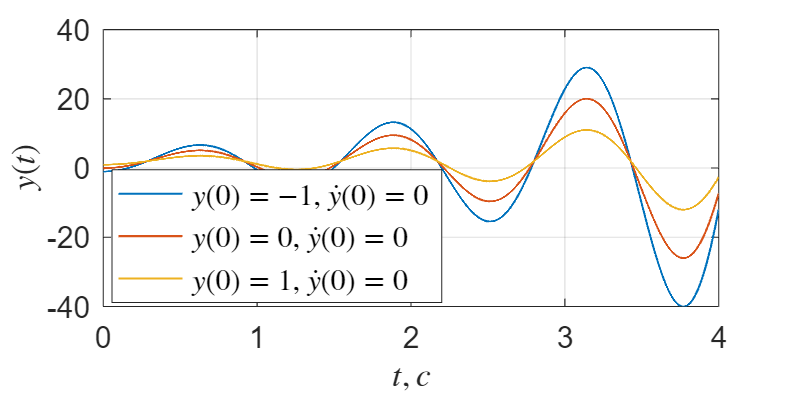

a1_a0_arr = [ [7.4 38.69]; [0 841]; [-1.4 25.49] ];
y0_dot_y0_arr = [ [-1 0]; [0 0]; [1 0] ];

simtime = 4;

for i=1:3
    a_1 = a1_a0_arr(i,1);
    a_0 = a1_a0_arr(i,2);
    for k=1:3
        y_0 = y0_dot_y0_arr(k,1);
        dot_y_0 = y0_dot_y0_arr(k,2);
    
        plot_1 = sim("lab3_1_1.slx", simtime);
        plot(plot_1.y.Time, plot_1.y.Data, LineWidth=1, LineStyle="-", ...
            DisplayName=sprintf('$y(0)=%d, \\dot{y}(0)=%d$', y_0, dot_y_0));
        hold on;
    
    end
    grid on;
    legend(Location="best", FontSize=14, Interpreter="latex");
    xlabel("$t, c$", Interpreter="latex");
    ylabel("$y(t)$", Interpreter="latex");
    set(gcf, Position=[100, 100, 1200, 600]);   
    set(gca, FontSize=14);
    
    hold off;
    filename = sprintf('images/plot_1_u2_%d.png', i);
    exportgraphics(gcf, filename, 'Resolution', 200)
end

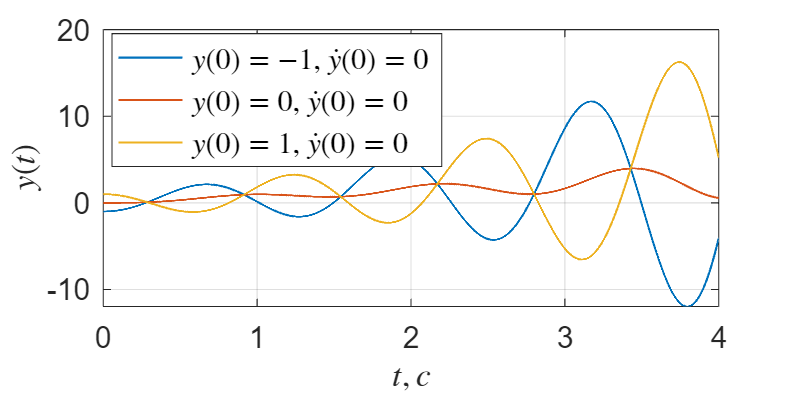


for i=1:3
    a_1 = a1_a0_arr(i,1);
    a_0 = a1_a0_arr(i,2);
    for k=1:3
        y_0 = y0_dot_y0_arr(k,1);
        dot_y_0 = y0_dot_y0_arr(k,2);
    
        plot_1 = sim("lab3_1_2.slx", simtime);
        plot(plot_1.y.Time, plot_1.y.Data, LineWidth=1, LineStyle="-", ...
            DisplayName=sprintf('$y(0)=%d, \\dot{y}(0)=%d$', y_0, dot_y_0));
        hold on;
    
    end
    grid on;
    legend(Location="best", FontSize=14, Interpreter="latex");
    xlabel("$t, c$", Interpreter="latex");
    ylabel("$y(t)$", Interpreter="latex");
    set(gcf, Position=[100, 100, 1200, 600]);   
    set(gca, FontSize=14);
    
    hold off;
    filename = sprintf('images/plot_1_u07t_%d.png', i);
    exportgraphics(gcf, filename, 'Resolution', 200)
end

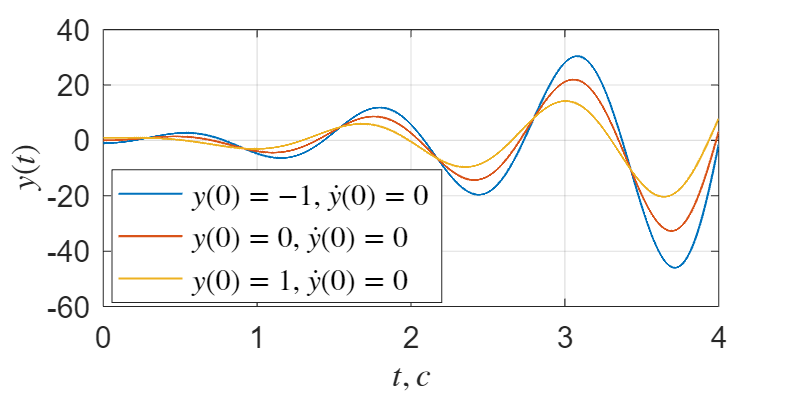


for i=1:3
    a_1 = a1_a0_arr(i,1);
    a_0 = a1_a0_arr(i,2);
    for k=1:3
        y_0 = y0_dot_y0_arr(k,1);
        dot_y_0 = y0_dot_y0_arr(k,2);
    
        plot_1 = sim("lab3_1_3.slx", simtime);
        plot(plot_1.y.Time, plot_1.y.Data, LineWidth=1, LineStyle="-", ...
            DisplayName=sprintf('$y(0)=%d, \\dot{y}(0)=%d$', y_0, dot_y_0));
        hold on;
    
    end
    grid on;
    legend(Location="best", FontSize=14, Interpreter="latex");
    xlabel("$t, c$", Interpreter="latex");
    ylabel("$y(t)$", Interpreter="latex");
    set(gcf, Position=[100, 100, 1200, 600]);   
    set(gca, FontSize=14);
    
    hold off;
    filename = sprintf('images/plot_1_ucos4t_%d.png', i);
    exportgraphics(gcf, filename, 'Resolution', 200)
end